# 4-Node Element

## Parameters

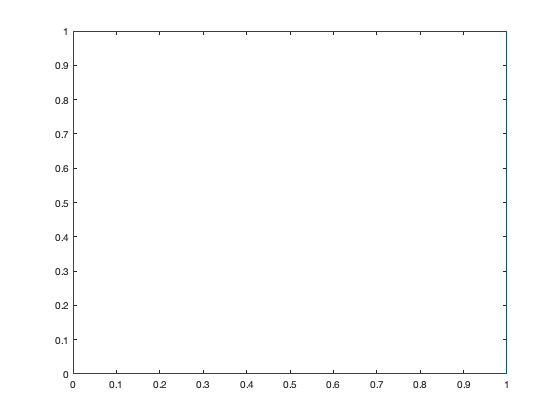

t = 1;
E = 1;
v = 0.2;
Coord = [
    0, 0;
    1, 0;
    1, 1;
    0, 1
];

% Coord = [
%     0, 0;
%     3, 2;
%     4, 4;
%     2, 5
% ];

plot([Coord(:,1); Coord(1,1)], [Coord(:,2); Coord(1,2)])

## Constitutive Law -- Plane Strain

C = (E/((1 + v)*(1 - 2*v))) ...
    * [
    1 - v, v, 0;
    v, 1 - v, 0;
    0, 0, (1 - 2*v)/2
    ];

% next Plane Stress
Cstress = (E/(1 + v)) ...
    * [
    1/(1 - v), v/(1 - v), 0;
    v/(1 - v), 1/(1 - v), 0;
    0, 0, 0.5
    ];

## Shape Functions

syms xi eta
N1 = (1 - xi)*(1 - eta)/4;
N2 = (1 + xi)*(1 - eta)/4;
N3 = (1 + xi)*(1 + eta)/4;
N4 = (1 - xi)*(1 + eta)/4;
Ni = [N1, N2, N3, N4];

## Coordinate Mapping

syms map
for n = 1:4
    map(n, 1) = Ni(n)*Coord(n, 1);
    map(n, 2) = Ni(n)*Coord(n, 2);
end

%    
%  (-1,1)    4--------------------3 (1,1) 
%            |                    |
%            |                    |
%            |          eta       |
%            |          |         |
%            |          --> xi    |
%            |                    |
%            |                    |
%            |                    |
%            |                    |
%  (-1,-1)   1--------------------2%   (1,-1) 
%
% newmap works korrekt
%newmap = subs(map, [xi, eta], [-1, 0])
%x = sum(newmap(:,1))
%y = sum(newmap(:,2))

x = sum(map(:,1))

$$x = \frac{\left(\eta +1\right)\,\left(\xi +1\right)}{4}-\frac{\left(\eta -1\right)\,\left(\xi +1\right)}{4}$$

y = sum(map(:,2))

$$y = \frac{\left(\eta +1\right)\,\left(\xi +1\right)}{4}-\frac{\left(\eta +1\right)\,\left(\xi -1\right)}{4}$$

CoordMap = [x, y]

$$CoordMap = \left(\begin{array}{cc} \frac{\left(\eta +1\right)\,\left(\xi +1\right)}{4}-\frac{\left(\eta -1\right)\,\left(\xi +1\right)}{4} & \frac{\left(\eta +1\right)\,\left(\xi +1\right)}{4}-\frac{\left(\eta +1\right)\,\left(\xi -1\right)}{4} \end{array}\right)$$

## Jacobian Matrix

NatCoord = [xi, eta];
for n = 1:2
    for m = 1:2
        J(n,m) = diff(CoordMap(n), NatCoord(m));
    end
end

Jinv = inv(J);

## B Matrix

B1 = [
    1, 0, 0, 0;
    0, 0, 0, 1;
    0, 1, 1, 0
    ];

B2 = [
    Jinv(1,1), Jinv(1,2), 0, 0;
    Jinv(2,1), Jinv(2,2), 0, 0;
    0, 0, Jinv(1,1), Jinv(1,2);
    0, 0, Jinv(2,1), Jinv(2,2);
    ];

syms B3
for n = 1:4
    B3(1, 2*n - 1) = diff(Ni(n), xi);
    B3(3, 2*n) = diff(Ni(n), xi);
    B3(2, 2*n - 1) = diff(Ni(n), eta);
    B3(4, 2*n) = diff(Ni(n), eta);    
end

B = B1*B2*B3;

## Stiffness Matrix

IntFunc = ( B' * C * B )* det(J);
ke = t * int(int(IntFunc, xi, -1, 1), eta, -1, 1); 

### Stiffnes Matrix (Actual Integration)

double(ke)

ans =     0.5093    0.1736   -0.3009   -0.0347   -0.2546   -0.1736    0.0463    0.0347
    0.1736    0.5093    0.0347    0.0463   -0.1736   -0.2546   -0.0347   -0.3009
   -0.3009    0.0347    0.5093   -0.1736    0.0463   -0.0347   -0.2546    0.1736
   -0.0347    0.0463   -0.1736    0.5093    0.0347   -0.3009    0.1736   -0.2546
   -0.2546   -0.1736    0.0463    0.0347    0.5093    0.1736   -0.3009   -0.0347
   -0.1736   -0.2546   -0.0347   -0.3009    0.1736    0.5093    0.0347    0.0463
    0.0463   -0.0347   -0.2546    0.1736   -0.3009    0.0347    0.5093   -0.1736
    0.0347   -0.3009    0.1736   -0.2546   -0.0347    0.0463   -0.1736    0.5093



xiset = [1/sqrt(3), -1/sqrt(3)];
etaset = [1/sqrt(3), -1/sqrt(3)];

kFull = 0;

for n = 1:2
    for m = 1:2
        kSmall = subs(IntFunc, [xi, eta], [xiset(n), etaset(m)]);
        kFull = kFull + kSmall;
    end
end

kFull = kFull * t;

### Stiffness Matrix (Full Gauss Integration)

double(kFull)

ans =     0.5093    0.1736   -0.3009   -0.0347   -0.2546   -0.1736    0.0463    0.0347
    0.1736    0.5093    0.0347    0.0463   -0.1736   -0.2546   -0.0347   -0.3009
   -0.3009    0.0347    0.5093   -0.1736    0.0463   -0.0347   -0.2546    0.1736
   -0.0347    0.0463   -0.1736    0.5093    0.0347   -0.3009    0.1736   -0.2546
   -0.2546   -0.1736    0.0463    0.0347    0.5093    0.1736   -0.3009   -0.0347
   -0.1736   -0.2546   -0.0347   -0.3009    0.1736    0.5093    0.0347    0.0463
    0.0463   -0.0347   -0.2546    0.1736   -0.3009    0.0347    0.5093   -0.1736
    0.0347   -0.3009    0.1736   -0.2546   -0.0347    0.0463   -0.1736    0.5093



kReduced = t * (2*2) * subs(IntFunc, [xi, eta], [0, 0]); 

### Stiffness Matrix (Reduced Gauss Integration)

double(kReduced)

ans =     0.3819    0.1736   -0.1736   -0.0347   -0.3819   -0.1736    0.1736    0.0347
    0.1736    0.3819    0.0347    0.1736   -0.1736   -0.3819   -0.0347   -0.1736
   -0.1736    0.0347    0.3819   -0.1736    0.1736   -0.0347   -0.3819    0.1736
   -0.0347    0.1736   -0.1736    0.3819    0.0347   -0.1736    0.1736   -0.3819
   -0.3819   -0.1736    0.1736    0.0347    0.3819    0.1736   -0.1736   -0.0347
   -0.1736   -0.3819   -0.0347   -0.1736    0.1736    0.3819    0.0347    0.1736
    0.1736   -0.0347   -0.3819    0.1736   -0.1736    0.0347    0.3819   -0.1736
    0.0347   -0.1736    0.1736   -0.3819   -0.0347    0.1736   -0.1736    0.3819
